To build the battery simulation, first run this section to load the .mat file that contains the battery model that you want to load

clear
clc
load("VMTest11.mat")

This needs to be done so that the library for the battery is in the is in the workspace as shown below

Next, load the .slx file that has the same name as the file you just loaded. 

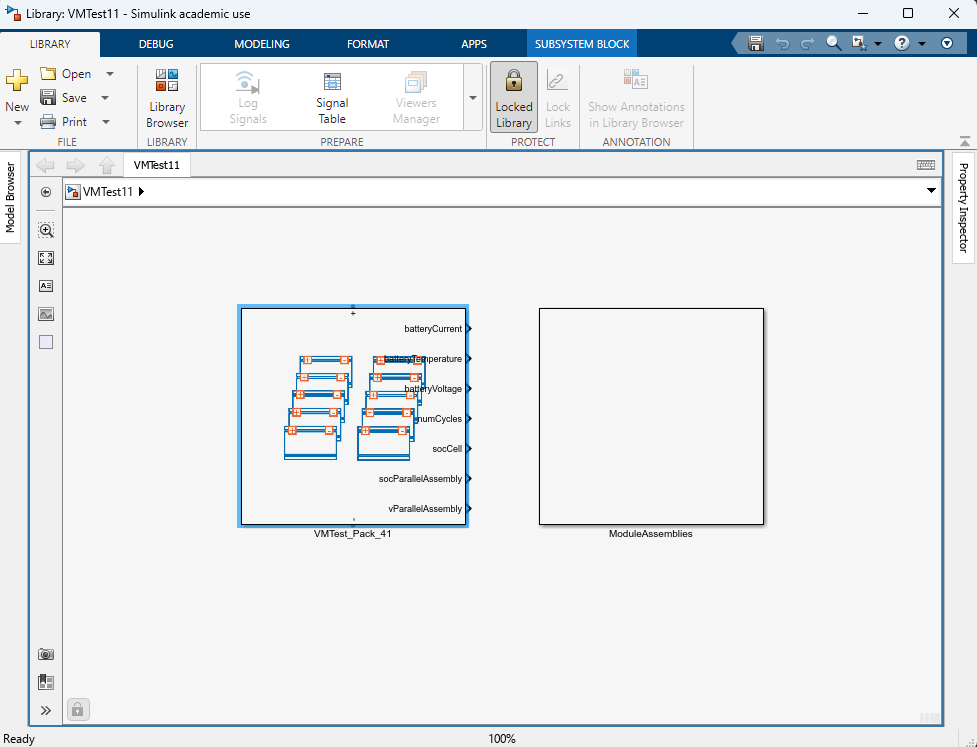

Next, copy the box on the left hand side by either doing ctrl+c or by right clicking it and copying it that way. 

Next, Load a blank simulink model and paste the battery pack by doing ctrl+v 

Then add an electrical reference and connect it to the negative terminal on the battery model

Then add a solver configuration block and connect it to the electrical reference. 

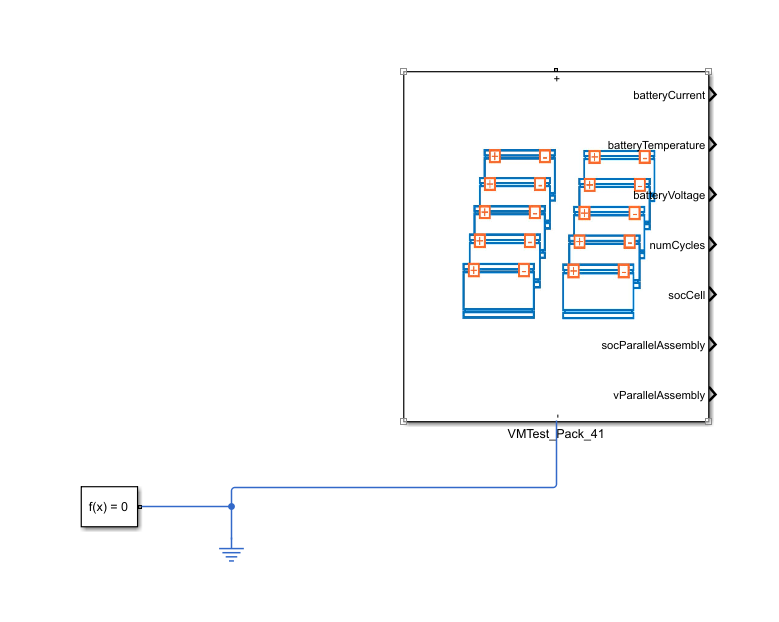

Next, connect displays to the batteryCurrent and batteryVoltage ports. Note that the batteryCurrent will show the current for the whole battery, while batteryVoltage will display the voltage per cell of the battery. 

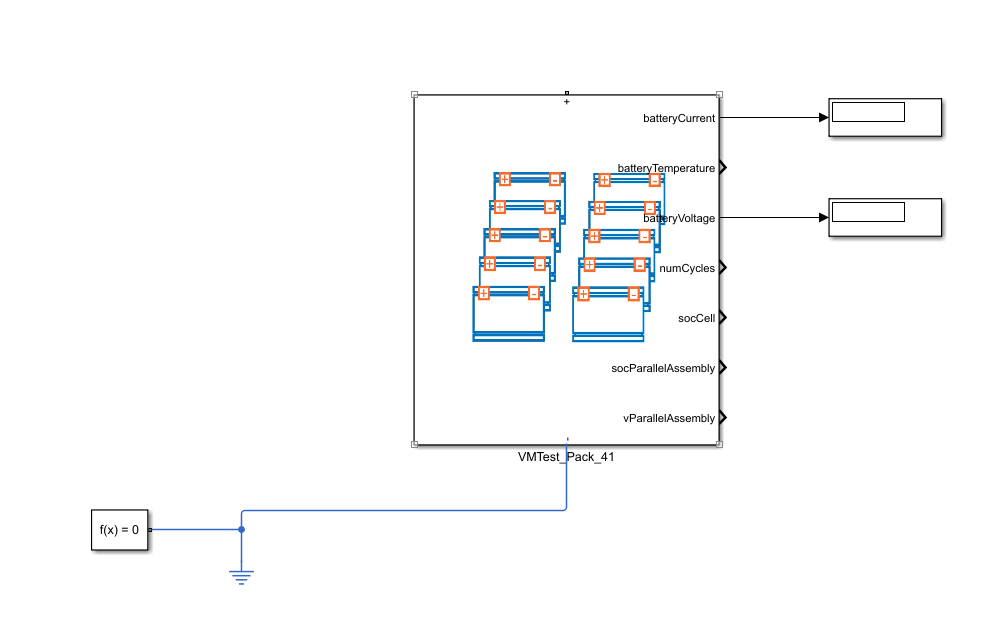

Next you will put in a signal editor editor block. This block will allow you to load the flight data in a way that is usable in simulink. 

Next, you must load the flight data into the signal editor. To do this, run the code below and follow the steps outlined.

% This is where you will upload the .BIN files from the flight logs
FlightData = ardupilotreader("C:\Users\Jordan Baylos\Desktop\DUST Battery\00000016.BIN");

% These will load all of the data that will go into the dataset file
SID_Data = readMessages(FlightData,"MessageNames","BAT");
Voltage = SID_Data.MsgData{1,1}.Volt(1:end);
Current = SID_Data.MsgData{1,1}.Curr(1:end);
VoltR = SID_Data.MsgData{1,1}.VoltR(1:end);
CurrentTotal = SID_Data.MsgData{1,1}.CurrTot(1:end);
EnergyTotal = SID_Data.MsgData{1,1}.EnrgTot(1:end);
Temperature = SID_Data.MsgData{1,1}.Temp(1:end);
Resistance = SID_Data.MsgData{1,1}.Res(1:end);
TimeStamp = duration(SID_Data.MsgData{1,1}.TimeUS(1:end)) - SID_Data.MsgData{1,1}.TimeUS(1);
Time = seconds(TimeStamp);
Voltage_ts = timeseries(Voltage, Time); Current_ts = timeseries(Current, Time);
VoltR_ts = timeseries(VoltR, Time); CurrentTotal_ts = timeseries(CurrentTotal, Time);
EnergyTotal_ts = timeseries(EnergyTotal, Time); Resistance_ts = timeseries(Resistance, Time);
% The code following this point wraps all of the data into a dataset file
% to be loaded into the signal editor
Battery_Data = Simulink.SimulationData.Dataset;
Battery_Data = Battery_Data.addElement(Voltage_ts, "Voltage");
Battery_Data = Battery_Data.addElement(Current_ts, "Current");
Battery_Data = Battery_Data.addElement(VoltR_ts, "VoltR");
Battery_Data = Battery_Data.addElement(CurrentTotal_ts, "Total Current");
Battery_Data = Battery_Data.addElement(EnergyTotal_ts, "Total Energy");
Battery_Data = Battery_Data.addElement(Resistance_ts, "Resistance");

You can either choose to manually load and save the file by uncommenting the line below, or load from the workspace and save the file that way, 

% save('Battery_Data.mat',"Battery_Data")

To load the file from the workspace, follow these steps.

Step 1: Click on the Signal Editor

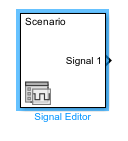

Step 2: Click on the open signal editor button on the top right

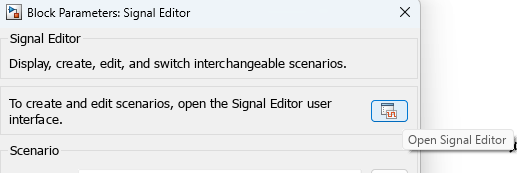

Step 3: Delete the blank dataset file in the signal editor by right clicking it and clicking delete

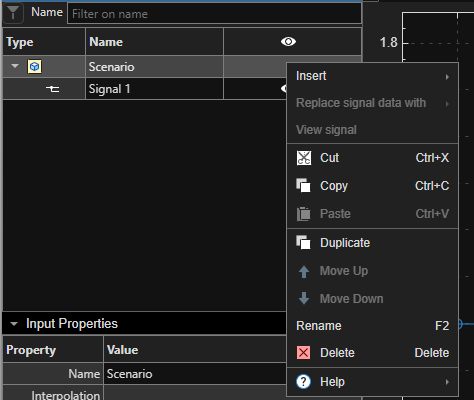

Step 4: Click on the signal editor tab on the top left

Step 5: Click on the import empty scenario button (bottom arrow) and then click from workspace

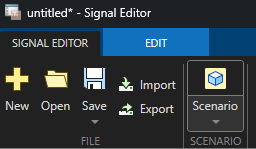

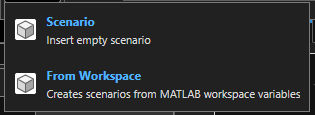

Step 6: Uncheck every box that is not the Battery_Data dataset file then press okay

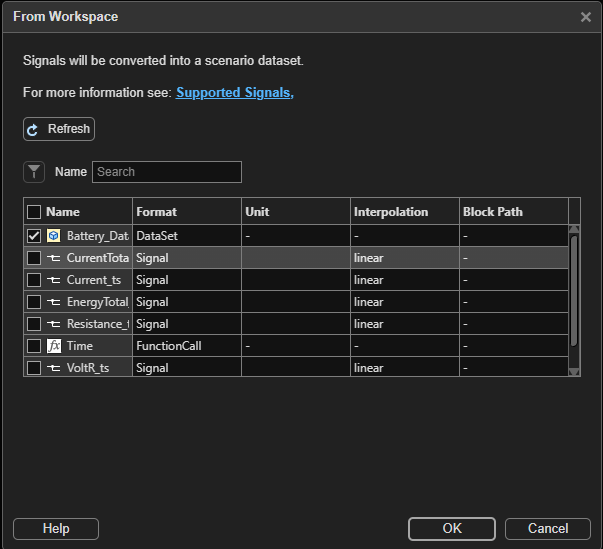

Your inputs should then look like this

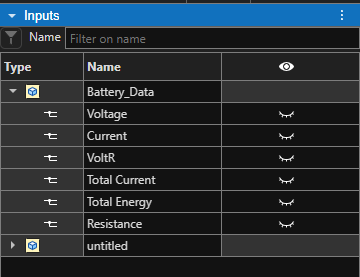

Step 7: Click save as and save the file as any name you want to use

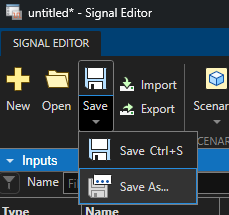

You will now see the name of the file that you saved it as as a .mat file on the singal editor block parameters

Step 8: Open the signal editor again and look at the current values. 

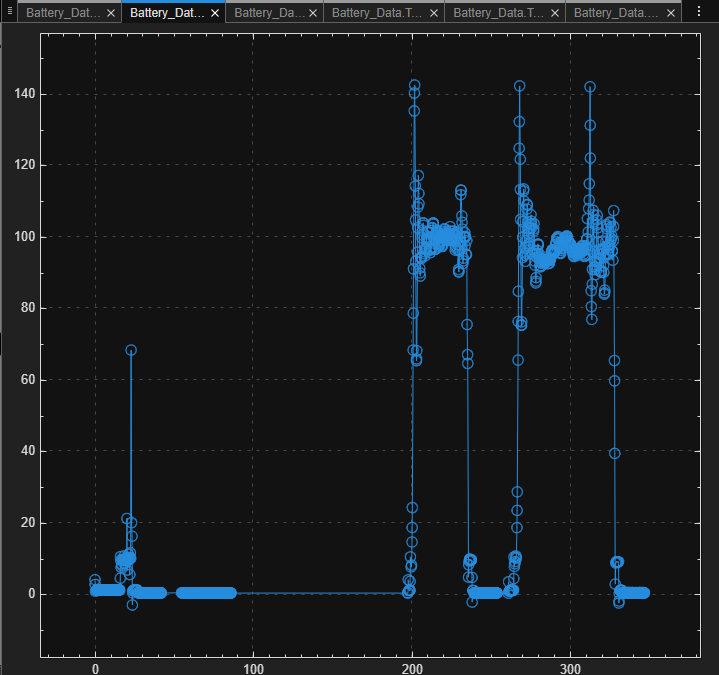

Now pick a time that represents the behavior that you are wanting to use to run your simulation, and see what time (x-axis) correlates to the behavior you want to simulate and input that time as your stop time at the top of the page. In our case here, we are trying to test hover flight and the most stable hover occurs somewhere around 235 seconds so that time will be used as our stop time. 

Step 9: Connect Displays to the voltage and the current ports on the signal editor

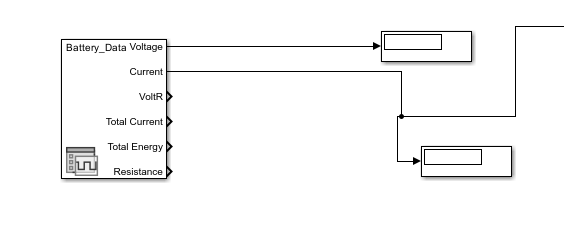

Step 10: Add a simulink to ps converter and add a controlled current source, then run a line from the current to the converter and connect the converter to the controlled current source. Connect the controlled current source so that it is going from positive to negative on one end and from negative to positive on the other end. This will make it so that the battery behaves like it is discharging. 

****NOTE**** I used ctrl+r to rotate the current source so that it naturally faces the way that I wanted it to

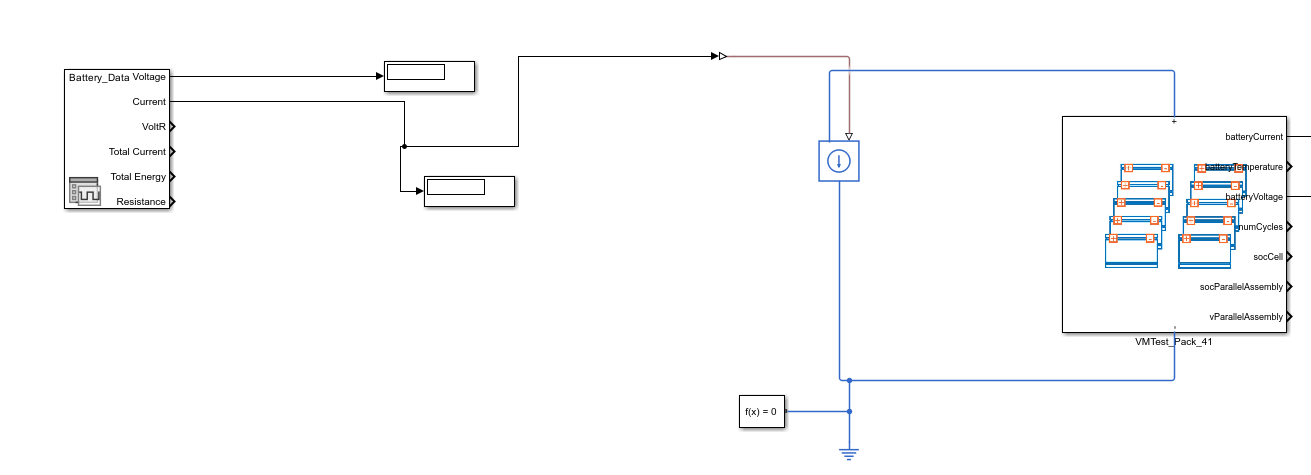

Step 11: Add a voltage sensor, a ps simulink converter, and a display block, Then connect the voltage sensor going from positive to positive, and from negative to negative on the battery. Then run the output of the voltage sensor to the ps simulink converter, then connect the converter to the display

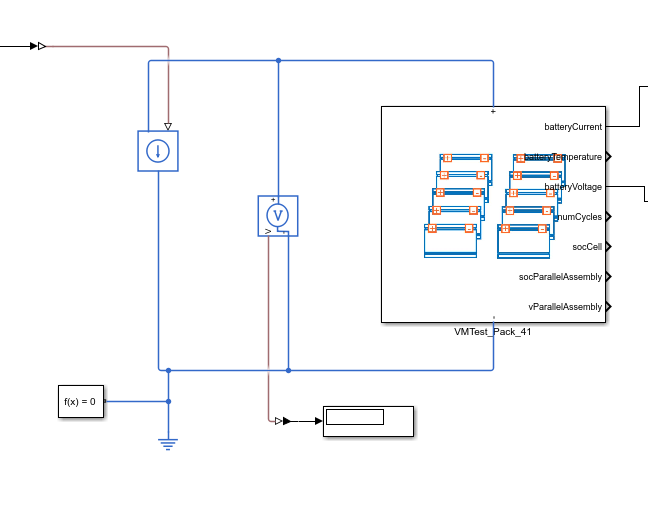

Step 12: Run your simulation via the run button and check the error between the physical data from the scopes attached to the signal editor and those that are being produced from the battery simulation. Make sure that you are looking at the scope labeled Voltage, not the scope labeled Voltage Per Cell. Then compute the percent error between the voltage being displayed by the voltage scope (simulation), and the voltage being produced by the singal editor (physical data). You ideally want this error to be below 6%. In this case, the error is 5.9%, which is just acceptable.